# Langtidsdrift

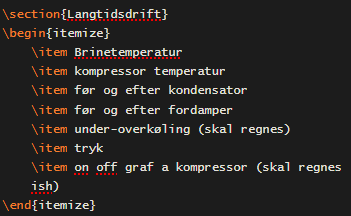

clc; clear all;


LTD = importdata("LangTidsDrift.txt");



## Brine


LTD_Tbrine = find(LTD.textdata(1,2:end) == "Brinetemperatur")

LTD_Tbrine = 4




ind = 10;

LTD_Tbrine = LTD.data(ind:end-ind, LTD_Tbrine);



ind_plot = find(max(LTD_Tbrine) == LTD_Tbrine)

ind_plot = 12958


xs = length(LTD_Tbrine(ind:end))*2*0.142/60

xs = 69.9113

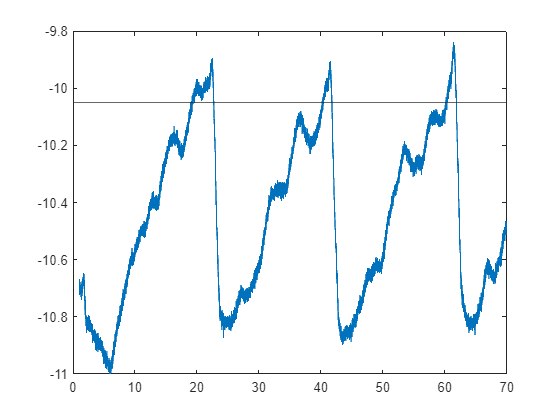


xlin = linspace(1,xs, length(LTD_Tbrine(ind:end)));



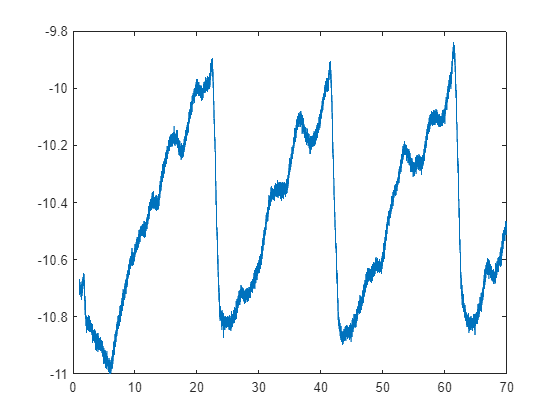


plot(xlin, LTD_Tbrine(ind:end))

## Tryk

LTD_lavtryk = find(LTD.textdata(1,2:end) == "Tryk lav")

LTD_lavtryk = 13

LTD_hojtryk = find(LTD.textdata(1,2:end) == "Tryk høj")

LTD_hojtryk = 12

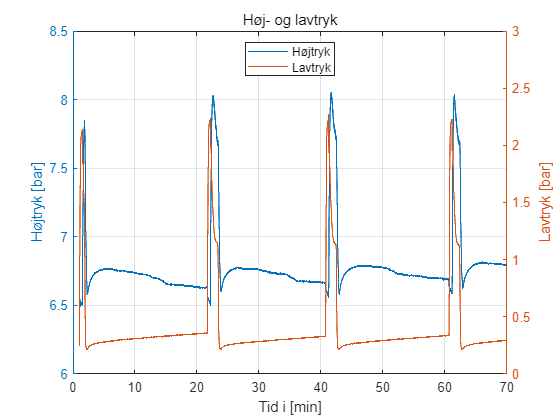


LTD_lavtryk = LTD.data(ind:end-19, LTD_lavtryk) +1;
LTD_hojtryk = LTD.data(ind:end-19, LTD_hojtryk) +1;


figure

yyaxis left
plot(xlin, LTD_hojtryk)
ylabel("Højtryk [bar]")
ylim([6,8.5])

yyaxis right
plot(xlin, LTD_lavtryk)
ylabel("Lavtryk [bar]")

ylim([0,3])

grid("on")
legend("Højtryk","Lavtryk","Location","north")
title("Høj- og lavtryk","FontWeight","normal")
xlabel("Tid i [min]")

## Entalpier

## Temp før og efter kondensator



T_kond_for   = find(LTD.textdata(1,2:end) == "Temperatur efter kompressor")

T_kond_for = 10

T_kond_efter = find(LTD.textdata(1,2:end) == "Temperatur efter kondensator ")

T_kond_efter = 11

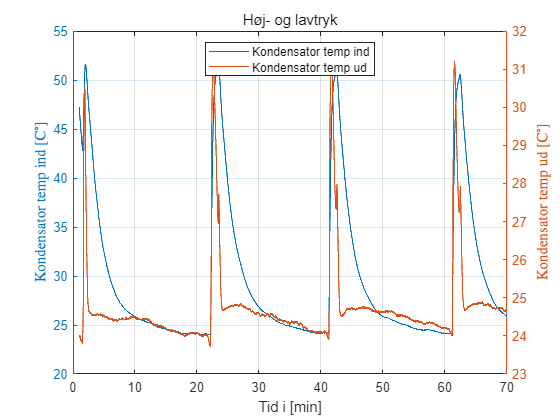




T_kond_for   = LTD.data(ind:end-19, T_kond_for);
T_kond_efter = LTD.data(ind:end-19, T_kond_efter);


figure

yyaxis left
plot(xlin, T_kond_for)
ylabel("Kondensator temp ind [C$^\circ$]", "Interpreter","latex")


yyaxis right
plot(xlin, T_kond_efter)
ylabel("Kondensator temp ud [C$^\circ$]", "Interpreter","latex")



grid("on")
legend("Kondensator temp ind","Kondensator temp ud","Location","north")
title("Kølemiddels temperatur ind og ud af kondensatoren","FontWeight","normal")
xlabel("Tid i [min]")

## Temp før og efter fordamper


T_fordamp_for = find(LTD.textdata(1,2:end) == "Temperatur efter EPV")

T_fordamp_for = 9

T_fordamp_efter = find(LTD.textdata(1,2:end) == "Temperaturen efter fordamper")

T_fordamp_efter = 6

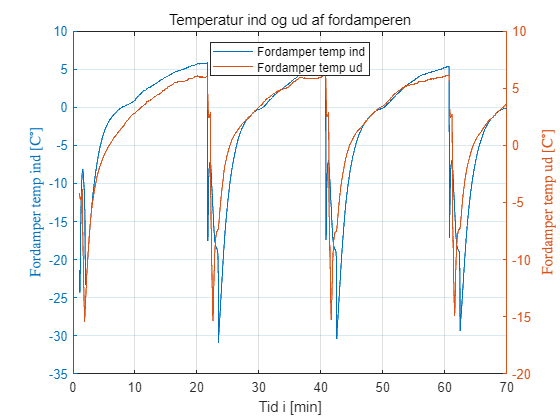



T_fordamp_for = LTD.data(ind:end-19, T_fordamp_for);
T_fordamp_efter = LTD.data(ind:end-19, T_fordamp_efter);


figure

yyaxis left
plot(xlin, T_fordamp_for)
ylabel("Fordamper temp ind [C$^\circ$]", "Interpreter","latex")


yyaxis right
plot(xlin, T_fordamp_efter)
ylabel("Fordamper temp ud [C$^\circ$]", "Interpreter","latex")



grid("on")
legend("Fordamper temp ind","Fordamper temp ud","Location","north")
title("Temperatur ind og ud af fordamperen","FontWeight","normal")
xlabel("Tid i [min]")

## Motortemperatur

## Kompressortemperatur

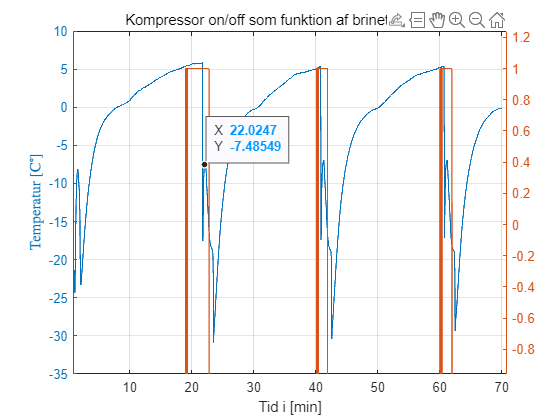

LTD_komptemp = find(LTD.textdata(1,2:end) == "Kompressortemperatur");

LTD_komptemp = LTD.data(ind:end-19, LTD_komptemp);


onoff = zeros(1, length(LTD_komptemp));

for i = 1:length(LTD_komptemp)
    if LTD_Tbrine(i) > -10.072
        onoff(i) = 1;
    else
        onoff(i) = -1;
    end
end



figure
yyaxis left
plot(xlin, T_fordamp_for)

ylabel("Temperatur [C$^\circ$]", "Interpreter","latex")



yyaxis right
plot(xlin, onoff)

ylim([-1.1,1.1])

grid("on")
xlabel("Tid i [min]")
title("Kompressor on/off som funktion af brinetempetatur","FontWeight","normal")